%1
clear
clf
load spectra.mat
who


Your variables are:

CIED50       CIED65       R1           R2           Tungsten60W  XYZ          ans          chips20      f11          plank90K     wavelength   xyz          



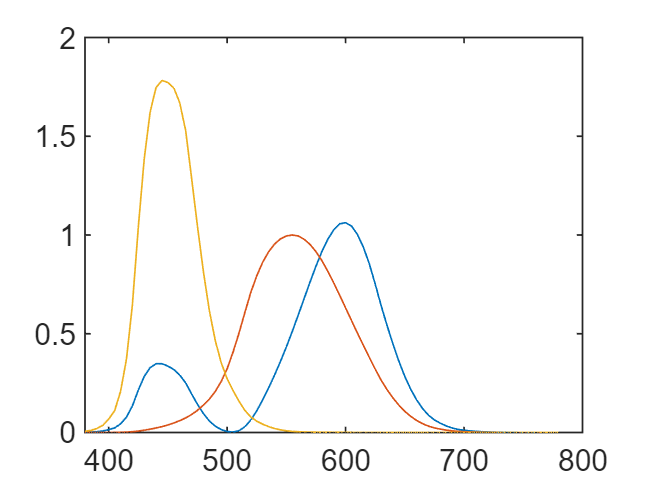

plot(wavelength, xyz)

%1.1
reflectAll = ones(length(CIED65), 1);
[X, Y, Z] = spectra2xyz(reflectAll, CIED65)

X = 96.4176

Y = 100.0000

Z = 82.5103

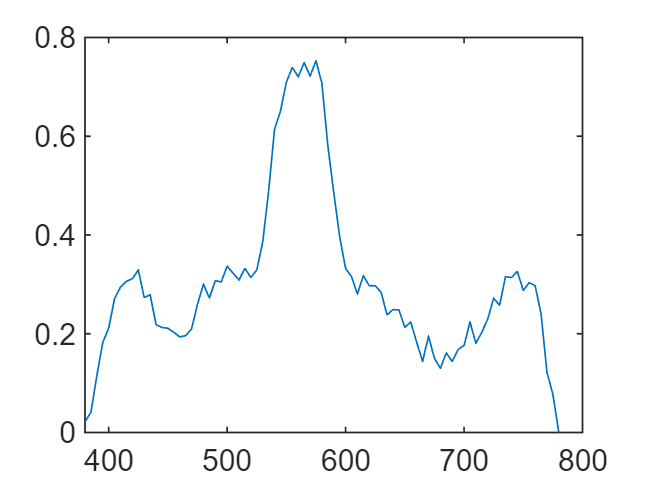

%1.2
plot(wavelength, R1)

[X1, Y1, Z1] = spectra2xyz(R1, CIED65)

X1 = 30.6805

Y1 = 31.8205

Z1 = 26.2552

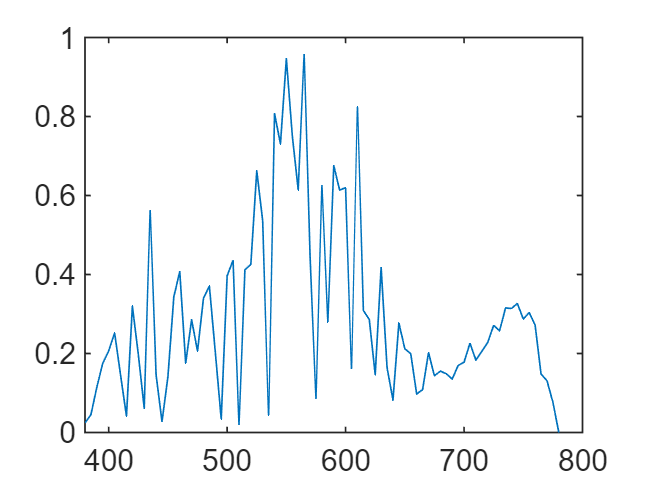

plot(wavelength, R2)

[X2, Y2, Z2] = spectra2xyz(R2, CIED65)

X2 = 29.9603

Y2 = 31.0734

Z2 = 25.6388

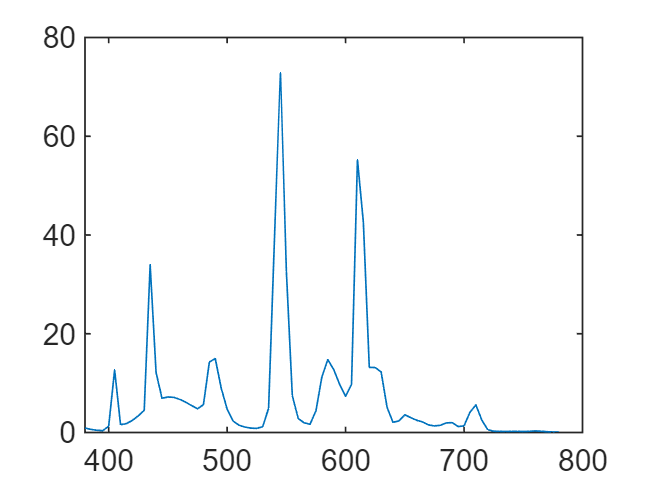

%1.3
plot(wavelength, f11)

[X3, Y3, Z3] = spectra2xyz(R1, f11)

X3 = 38.8438

Y3 = 40.2871

Z3 = 33.2410

[X4, Y4, Z4] = spectra2xyz(R2, f11)

X4 = 46.8186

Y4 = 48.5581

Z4 = 40.0654

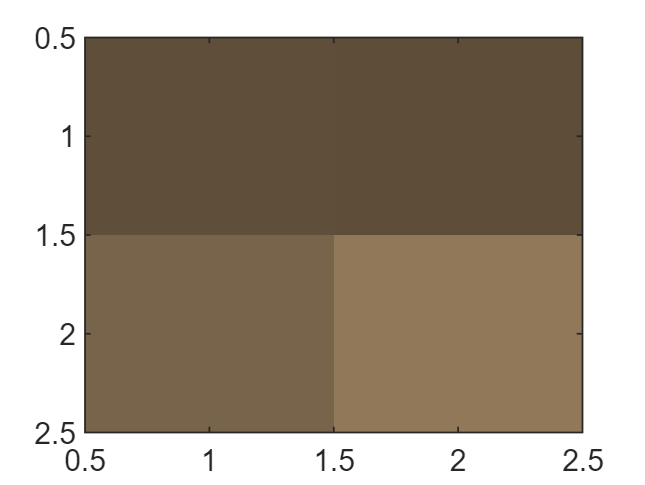

%1.5
[r1, g1, b1] = myxyz2rgb(X1, Y1, Z1);
[r2, g2, b2] = myxyz2rgb(X2, Y2, Z2);
[r3, g3, b3] = myxyz2rgb(X3, Y3, Z3);
[r4, g4, b4] = myxyz2rgb(X4, Y4, Z4);
map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4];
map=min(1,max(0,map));
image([1 2; 3 4])
colormap(map)
imwrite(colormap(map), "yourfilename", "png")

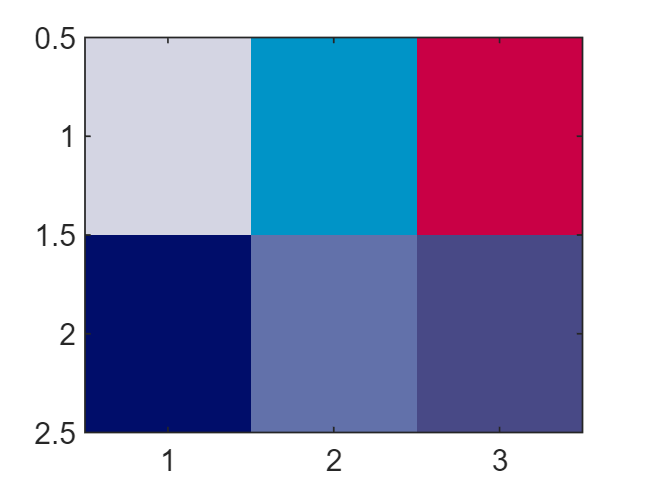

%2.2
[r1, g1, b1] = myxyz2rgb(80.43, 84, 96.5);
[r2, g2, b2] = myxyz2rgb(25.84, 42.52, 80.88);
[r3, g3, b3] = myxyz2rgb(37.36, 18.44, 27.52);
[r4, g4, b4] = myxyz2rgb(7.40, 5.74, 40.36);
[r5, g5, b5] = myxyz2rgb(43.915, 44.87, 69.43);
[r6, g6, b6] = myxyz2rgb(31.6, 30.48, 54.2);
map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4; r5 g5 b5; r6 g6 b6];
map=min(1,max(0,map));
image([1 2 3; 4 5 6])
colormap(map)
imwrite(colormap(map), "yourfilename", "png")